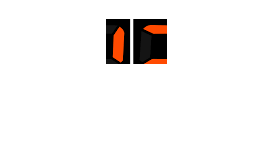

% Load image
[A,c] = imread('numbers.png');
A = A(1:45,30:90);
imshow(A,c)

[n,m] = size(A);
NM = n*m;

% Define labels
L = [1, 2, 3]; % 1 - white, 2 - black, 3 - red
% Define seeds
% S = [3, 4, 2; 10, 4, 2; 10, 10, 2; 3, 10, 2;
%     12, 6, 1; 4, 6, 1];

S = [13, 13, 3; 31, 12, 3; 37, 16, 3; 42, 14, 3; 10, 43, 3; 12, 51, 3; 11, 59, 3; 44, 46, 3; 42, 52, 3; 44, 59, 3;
    37, 56, 2; 32, 44, 2; 23, 48, 2; 17, 58, 2; 11, 34, 2; 12, 30, 2; 38, 30, 2; 38, 23, 2; 5, 22, 2; 4, 11, 2; 3, 12, 2; 24, 4, 2; 37, 4, 2; 45, 5, 2; 13, 4, 2;
    42, 25, 1; 36, 27, 1; 20, 25, 1; 16, 27, 1; 6, 27, 1; 10, 25, 1];

T = 500; % Number of steps
LD = zeros(NM, numel(L));  % initalize limiting distribution
img = zeros(n,m,3);
for p = 1:3
    for i = 1:n
        for j = 1:m
            img(i,j,p) = c(A(i,j)+1,p);
        end
    end
end

tic
W = sparse(calculate_weights(img,300));
toc

Elapsed time is 0.042285 seconds.


tic
H = construct_hamiltonian(W, 0.001);
toc

Elapsed time is 0.068650 seconds.


tic 
U = construct_operator(H);
toc

Elapsed time is 2.814404 seconds.


for i = 1:numel(L) % use parfor if available
    sprintf("Working with label: %d", i)
    subset = seeds_subset(S,L(i));
    subset_length = size(subset,1);
    A_sub = zeros(numel(A),1);
    for p = 1:subset_length
        A_sub( subset(p,2) + m*(subset(p,1)-1) ) = 1;
    end
    state = 1/sqrt(subset_length) * sparse(A_sub);
    sprintf("The norm of our intial state vector is: %d", dot(full(state), full(state)))
    D = zeros(n*m,T);
    for t = 1:T
        state = U*state;
        % state = update_state(-1i, H, state);
        D(:,t) = retrieve_position(state);
    end
    sprintf("After %d steps, the norm is: %d", T, dot(full(state), full(state)))
    LD(:,i) = 1/T * sum(D,2);
    sprintf("Limiting distribution of label %d found", i)
end

ans = "Working with label: 1"

ans = "The norm of our intial state vector is: 1.000000e+00"

ans = "After 500 steps, the norm is: 1.000000e+00"

ans = "Limiting distribution of label 1 found"

ans = "Working with label: 2"

ans = "The norm of our intial state vector is: 1.000000e+00"

ans = "After 500 steps, the norm is: 1.000000e+00"

ans = "Limiting distribution of label 2 found"

ans = "Working with label: 3"

ans = "The norm of our intial state vector is: 1"

ans = "After 500 steps, the norm is: 1.000000e+00"

ans = "Limiting distribution of label 3 found"

B = zeros(n,m);
b = [4,1,2];
figure
for i = 1:n
    for j = 1:m
        k = find_seed(LD,i,j,m);
        B(i,j) = k;
    end
end

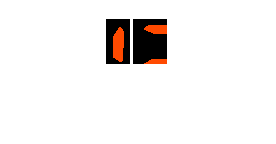

figure
imshow(B,c(b,:))